# Senior Capstone Constants & Linearization

### Amay Kejriwal, Jacob Wheelock, and Jonah Spencer

clear all;
close all;

#### Constants

General Constants

g = 9.81; %% Gravitational Acceleration (m/s^2)
delta_t = 0.001; %% Sampling Period (s)

Vehicle Parameters

m = 200; %% Vehicle Mass (kg)
mu = 0.9; %% Tire Coefficient of Friction
Mu = [0, 0, mu;
      0, 0, 0;
      0, 0, 0]; %% Friction Transformation Tensor
r = 0.229; %% Tire Radius (m)
i_0 = 3.27; %% Final Drive Ratio
i_p = 2.073; %% Primary Ratio
i_x = 2; %% Current Gear

Drag Force Constants (credit: Howard Wu)

C_D = 1.163; %% Coefficient of Drag
C_L = 2.135; %% Coefficient of Lift
A_f = 1.0782; %% Equivalent Frontal Area (m^2)
rho = 1.204; %% Density of Air (kg/m^3)

Constants Vector

const = [m g rho C_D A_f i_x i_0 i_p r];

#### Engine Model

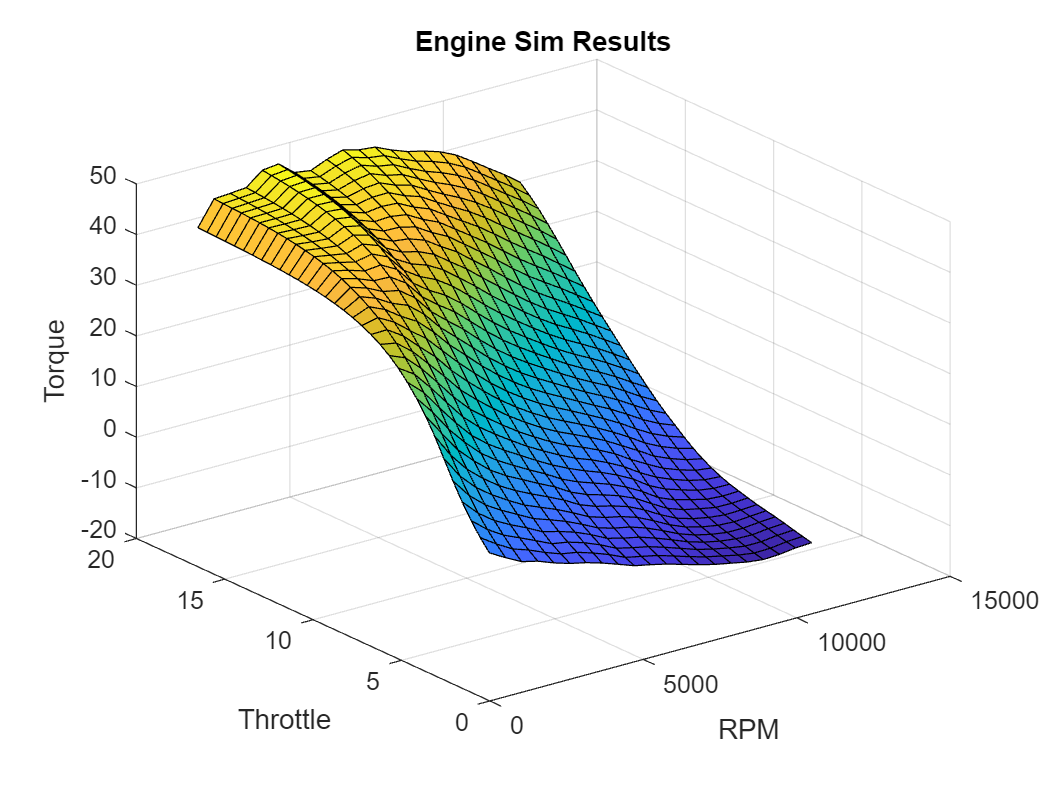

% Import results
Engine_Sim = readmatrix('TorqueVsInputs.xlsx');

RPM_In = Engine_Sim(1, 3:end); %% Extract RPM Input
Throttle_In = Engine_Sim(2:end, 2); %% Exract Throttle Input
Torque = Engine_Sim(2:end, 3:end); %% Extract Torque
n = length(RPM_In)*length(Throttle_In); %% Number of points

% Plot GT Suite Results
[X, Y] = meshgrid(RPM_In, Throttle_In);
figure;
surf(X, Y, Torque);
title 'Engine Sim Results'
xlabel 'RPM'
ylabel 'Throttle'
zlabel 'Torque'


% Create Two Column Input Vector
Input = zeros(n,2);
k = 1;
for i=1:length(RPM_In)
    for j=1:length(Throttle_In)
        Input(k, 1) = RPM_In(i);
        Input(k, 2) = Throttle_In(j);
        k = k + 1;
    end
end

% Reshape Output Vector
z = reshape(Torque, [length(RPM_In)*length(Throttle_In) 1]);

% Create Constants for Fit
x = Input(:,1);
y = Input(:,2);
one = ones(n,1);
degree = 10; %% Polynomial Fit Degree
o_of_m = [0]; %% Store Order of Magnitude of Coefficient
A_engine = [ones(n,1)];

for i = 1:degree
    scaleX = floor(log10(x(end).^i)); %% x^i order
    scaleY = floor(log10(y(end).^i)); %% y^i order
    o_of_m = [o_of_m scaleX scaleY];
    A_engine = [A_engine...
        10^(-1*scaleX)*x.^i...
        10^(-1*scaleY)*y.^i];
end

coef = A_engine\z;
coefscale = [coef'; o_of_m];

Z = coef(1)*ones(33,21);

for i = 2:length(coef)
    if(mod(i,2) == 0)
        Z = Z + (10^(-1*o_of_m(i)))*coef(i)*X.^floor(i/2);
    else
        Z = Z + (10^(-1*o_of_m(i)))*coef(i)*Y.^floor(i/2);
    end
end

error = norm(Z - Torque) - 87

error = 0.7809

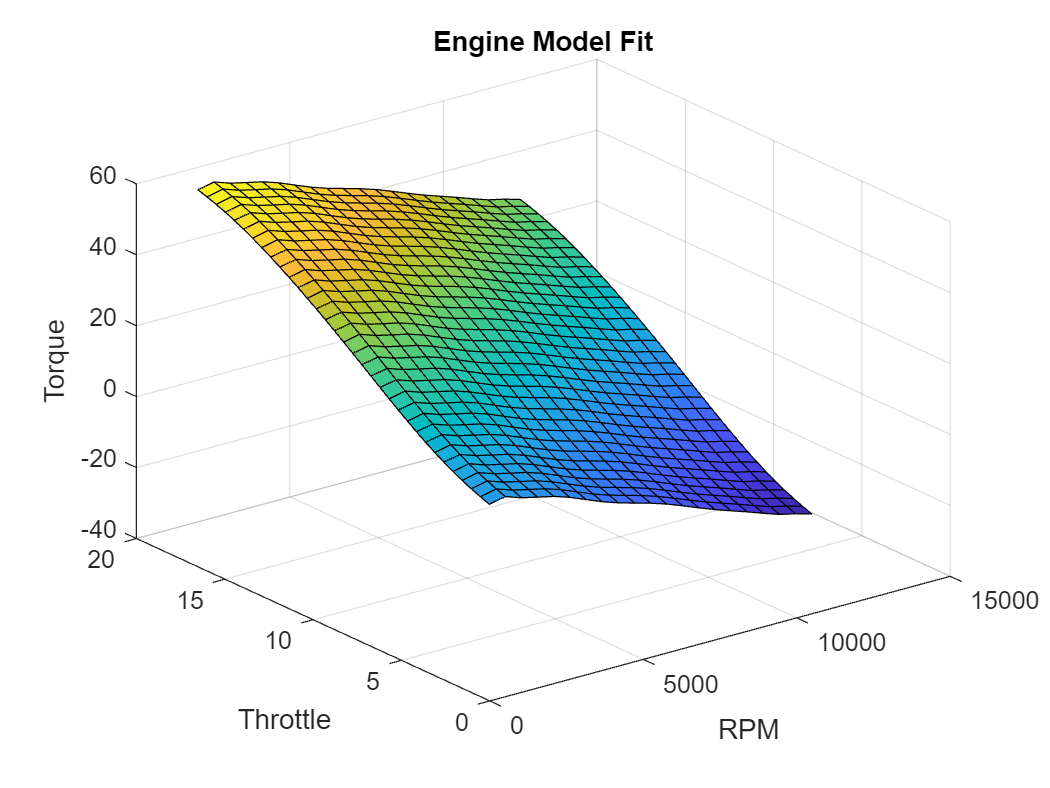


figure;
%surf(X, Y, Torque);
%hold on
surf(X, Y, Z);
title 'Engine Model Fit'
xlabel 'RPM'
ylabel 'Throttle'
zlabel 'Torque'

#### Linearization

% Create symbolic variables
V = sym('V', [3 1]); %% Velocity (m/s)
syms u %% Input (Throttle Position) (mm^2)
syms m g rho C_D A_f i_x i_0 i_p r %% Constants

% Forces
F_G = [0;0;m*g]; %% Weight Force (N)
F_L = [-1/2*rho*C_L*A_f*V(1)^2;0;0]; %% Lift Force (N)
F_D = [-1/2*rho*C_D*A_f*V(1)^2;0;0]; %% Drag Force (N)
F_N = -1*(F_G + F_L); %% Normal Force (N)

% Conversions
Wsp = [1/r,0,0]*V; %% Wheelspeed (rad/s)
RPM = Wsp * i_0 * i_p * i_x * 60/(2*pi); %% Engine Angular Speed (RPM)

% Calculate Wheel Force
coef = coefscale(1, :).*10.^(-1*coefscale(2, :)); %% Engine Model Coefficients

Reference to a cleared variable coefscale.

Tq = coef(1); %% Engine Model Constant
for i = 2:length(coef)
    if(mod(i,2) == 0)
        Tq = Tq + coef(i)*RPM^floor(i/2);
    else
        Tq = Tq + coef(i)*u^floor(i/2);
    end
end
F_W = [i_0 * i_x * Tq * 1/r; 0; 0]; %% Wheel Force (N)
F_b = F_W + F_D + F_G + F_L + F_N; %% Body Force (N)

% Linearization
V_dot = 1/m * F_b; %% Newton's Law
V_dot = subs(V_dot, [m g rho C_D A_f i_x i_0 i_p r], ...
    const); %% Substitute Constants
V_dot_L = jacobian(V_dot, V); %% Linearize
B_L = jacobian(V_dot, u); %% Linearize


% Plug in Equilibirum
V_eq = [10;0;0]; %% Equilibrium Velocity (m/s)
dA = subs(V_dot_L, V, V_eq) %% Linearized A
dA = double(dA);

% Find Equilibrium Input
xBalance = subs(F_W + F_D, V, V_eq);
xBalance = subs(xBalance, [m g rho C_D A_f i_x i_0 i_p r], const);
fun = @(p) double(subs(xBalance(1), u, p));
u_eq = fzero(fun, 6);
dB = subs(B_L, u, u_eq)
dB = double(dB);

% Create Linear Model
r = const(end);
C = [1/r 0 0]; %% Wheelspeed is Observed
D = [0];
SS = ss(dA, dB, C, D)
[b, a] = ss2tf(dA, dB, C, D);
TF = tf(b,a)

% Discretization
syms sigma
del_A = expm(dA*delta_t); %% Discrete Dynamics
del_B = double(int(expm(dA*(delta_t-sigma))*dB, 0, delta_t)); %% Discrete Input
del_SS = ss(del_A, del_B, C, D, delta_t)
del_TF = tf(b,a, delta_t)

% Plot Key Figures
figure;
bode(del_SS)
figure;
margin(del_SS)
figure;
pzmap(del_SS)
figure;
nyquist(del_SS)
figure;
rlocus(del_SS)
figure;
step(del_SS)
figure;
impulse(del_SS)

#### Controller

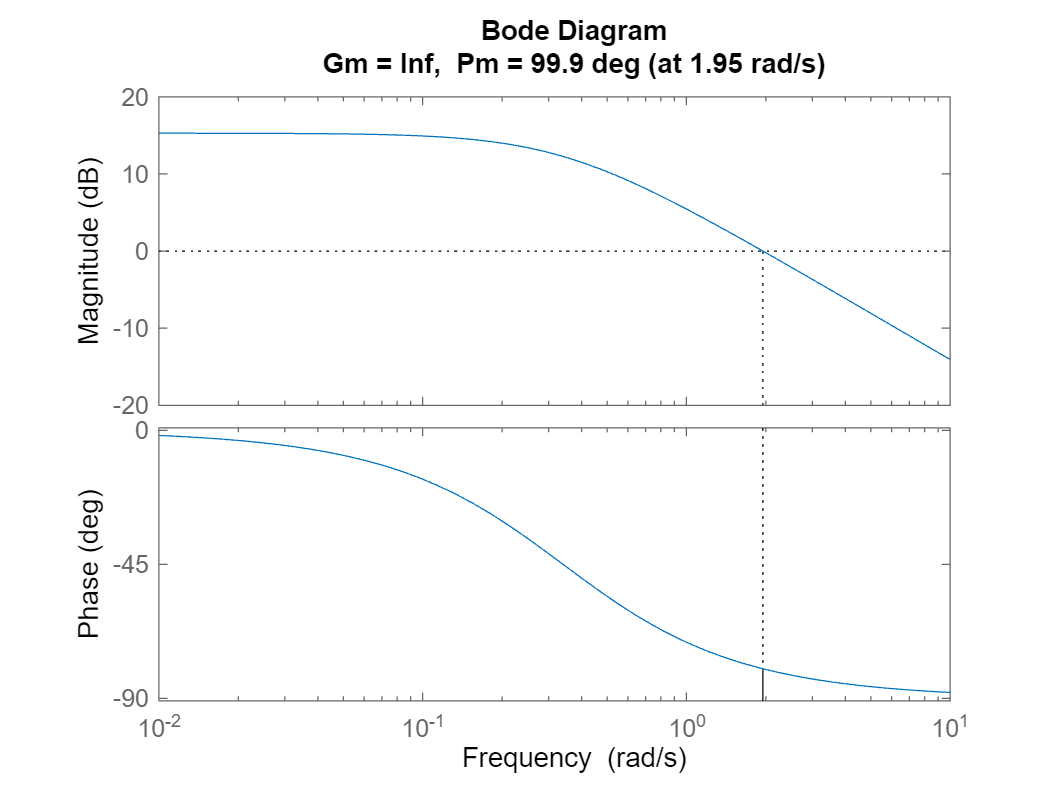

% Decouple System
A = dA(1,1);
B = dB(1);
C = C(1,1);
D = 0;

SS_vx = ss(A, B, C, D);
margin(SS_vx)


[p,z] = pzmap(SS_vx)

p = -0.3404


z =

  0×1 empty double column vector




rank(ctrb(SS_vx))

ans = 1

rank(obsv(SS_vx))

ans = 1


% LQR Controller
K = lqr(SS_vx, 1, 0.001)

K = 30.8799


% PID Controller
PID = pid(3,1.7)

PID =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 3, Ki = 1.7
 
Continuous-time PI controller in parallel form.



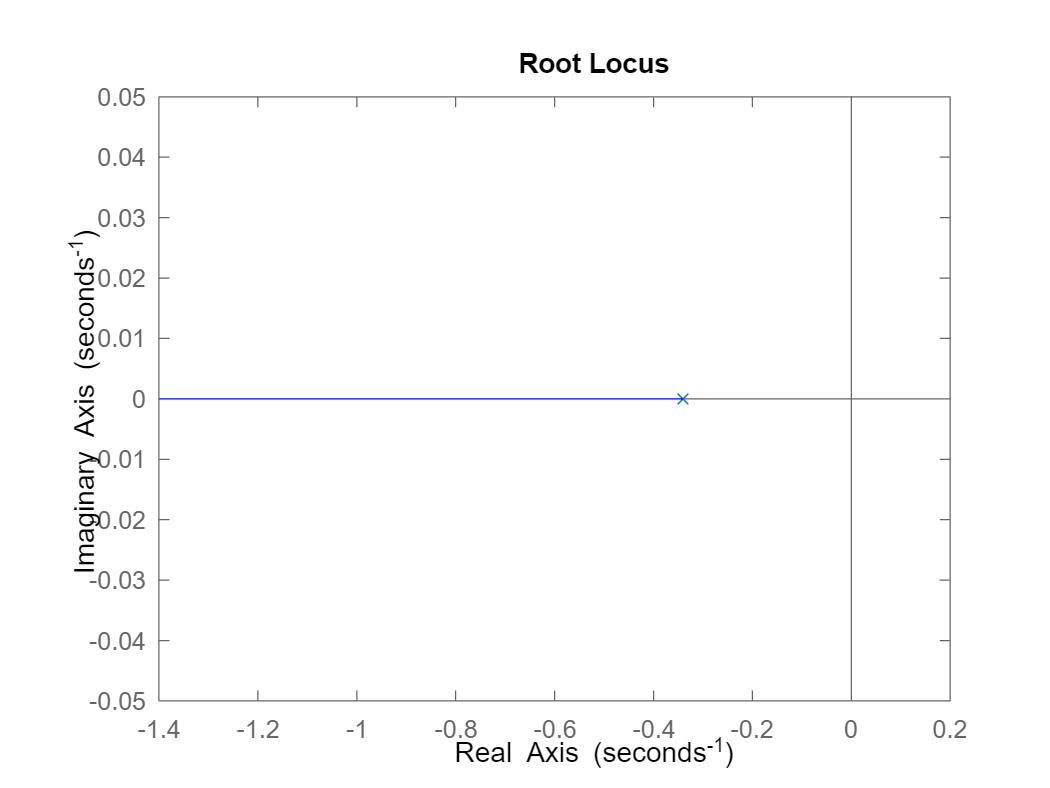


% Controlled System LQR
LQR_cl = feedback(SS_vx*K, 1);
rlocus(SS_vx*K)

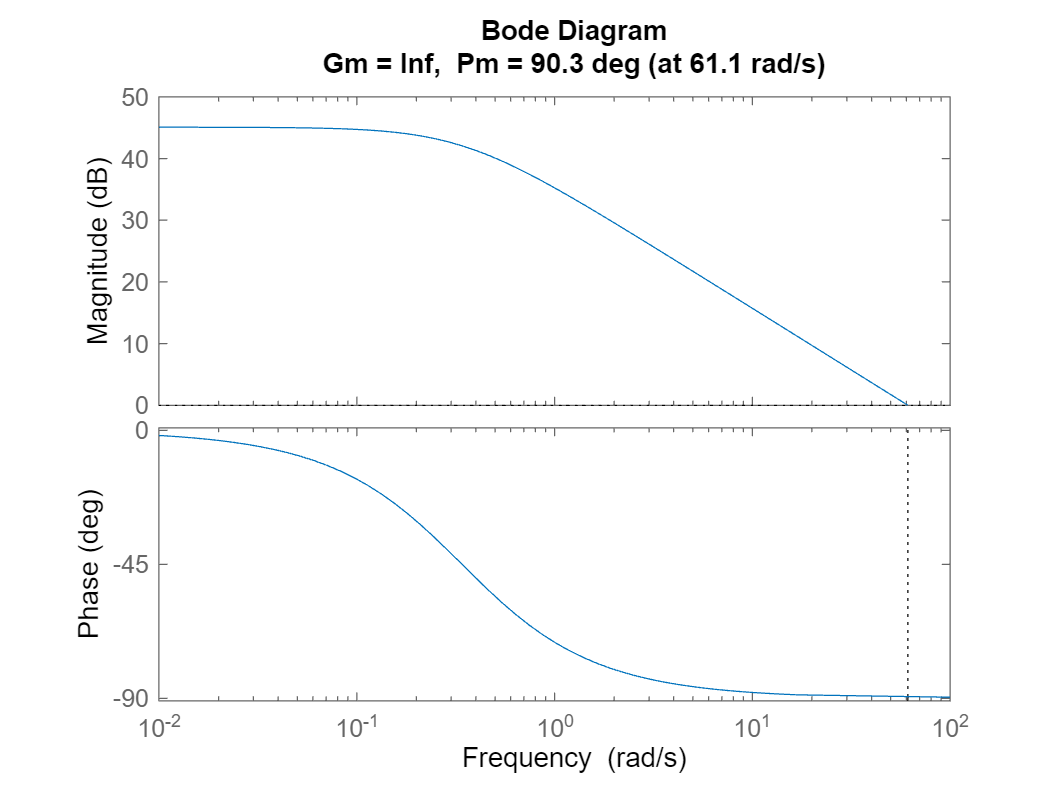

margin(SS_vx*K)

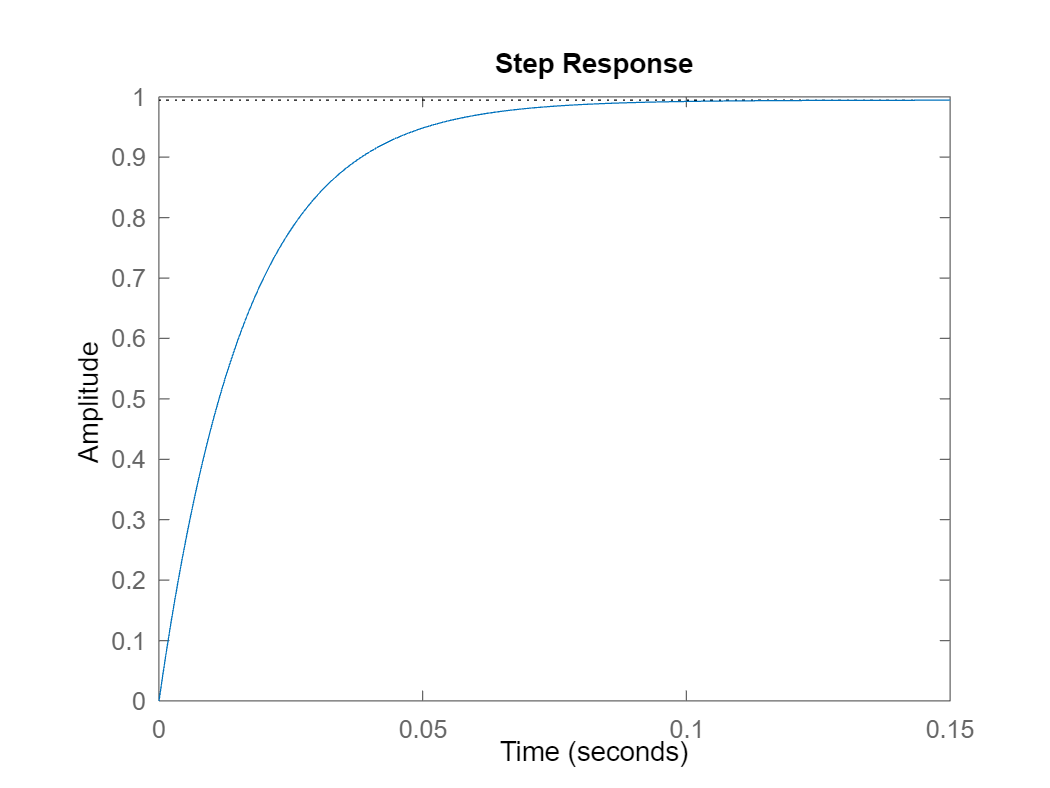

step(LQR_cl)

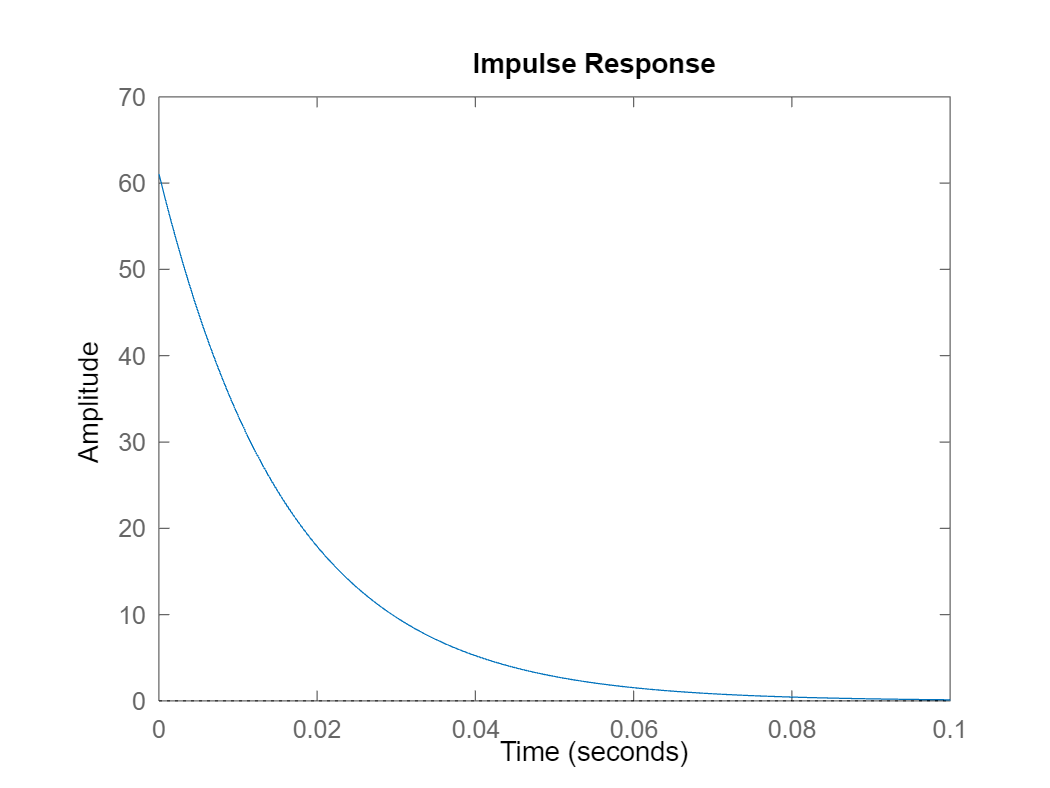

impulse(LQR_cl)

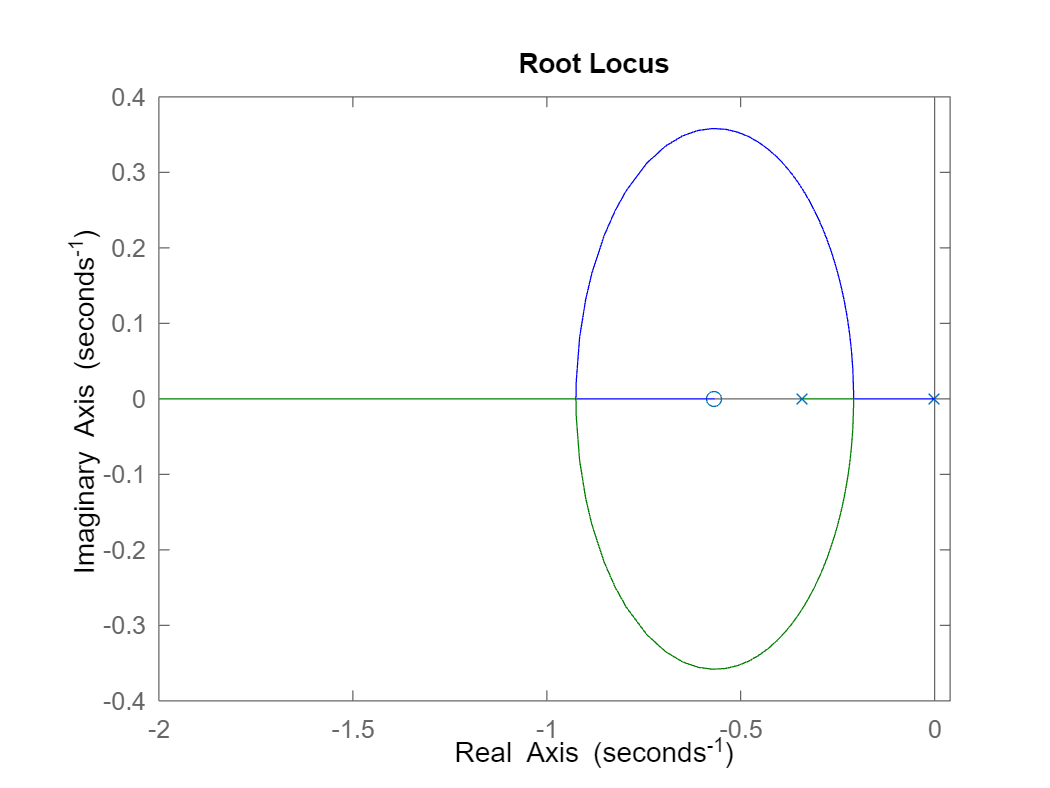


% Controller System PID
PID_cl = feedback(SS_vx*PID, 1);
rlocus(SS_vx*PID)

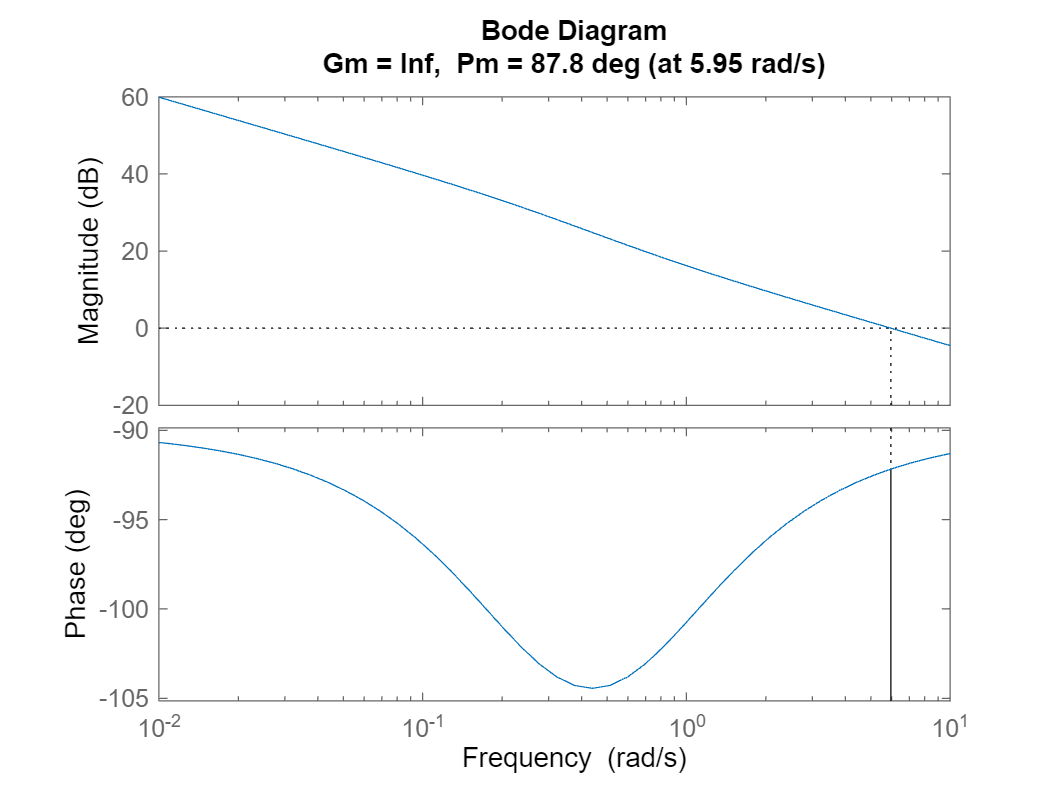

margin(SS_vx*PID)

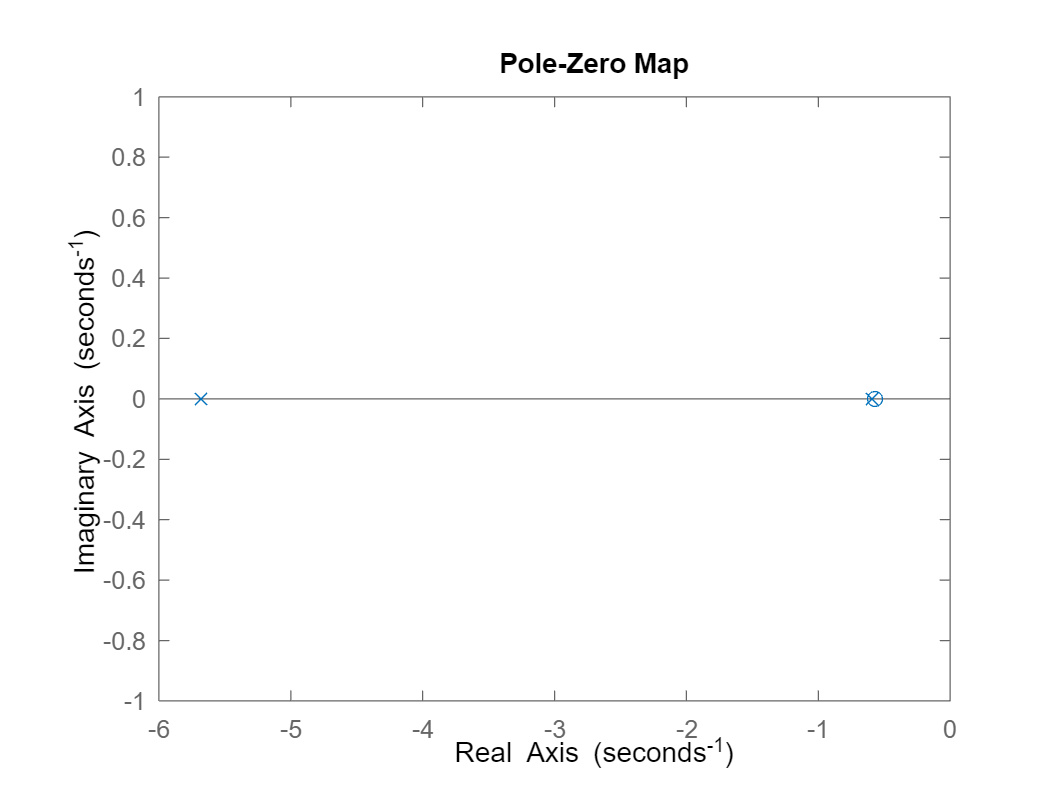

pzmap(PID_cl)

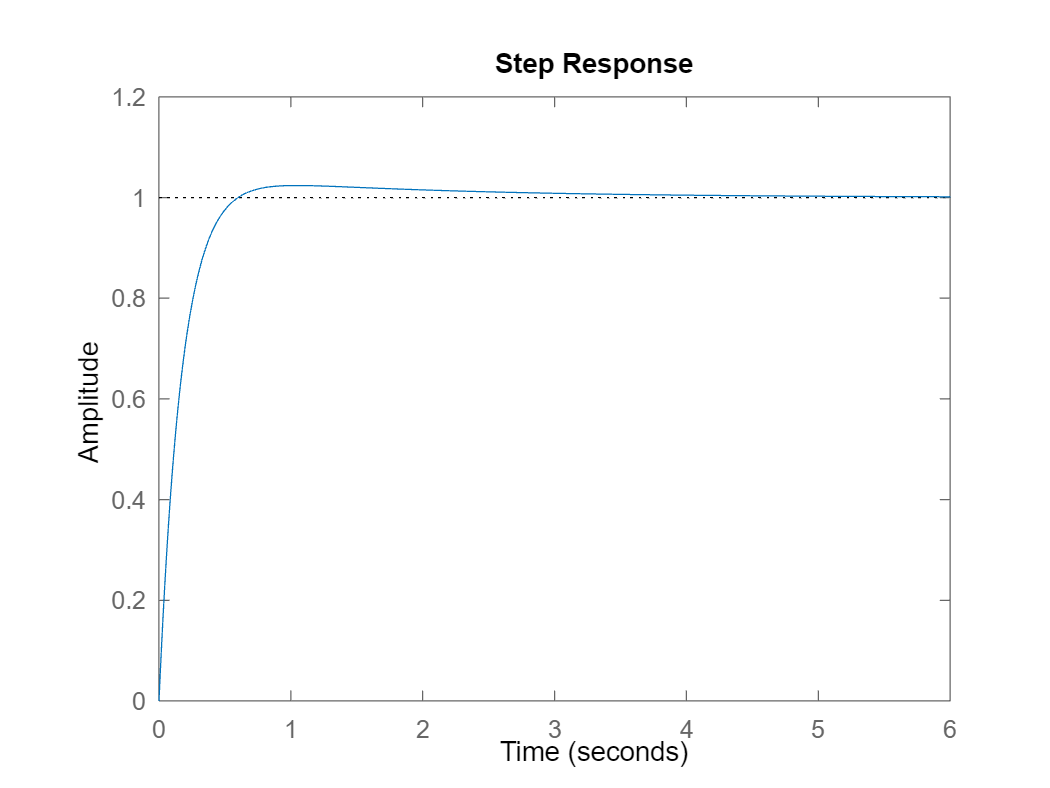

step(PID_cl)

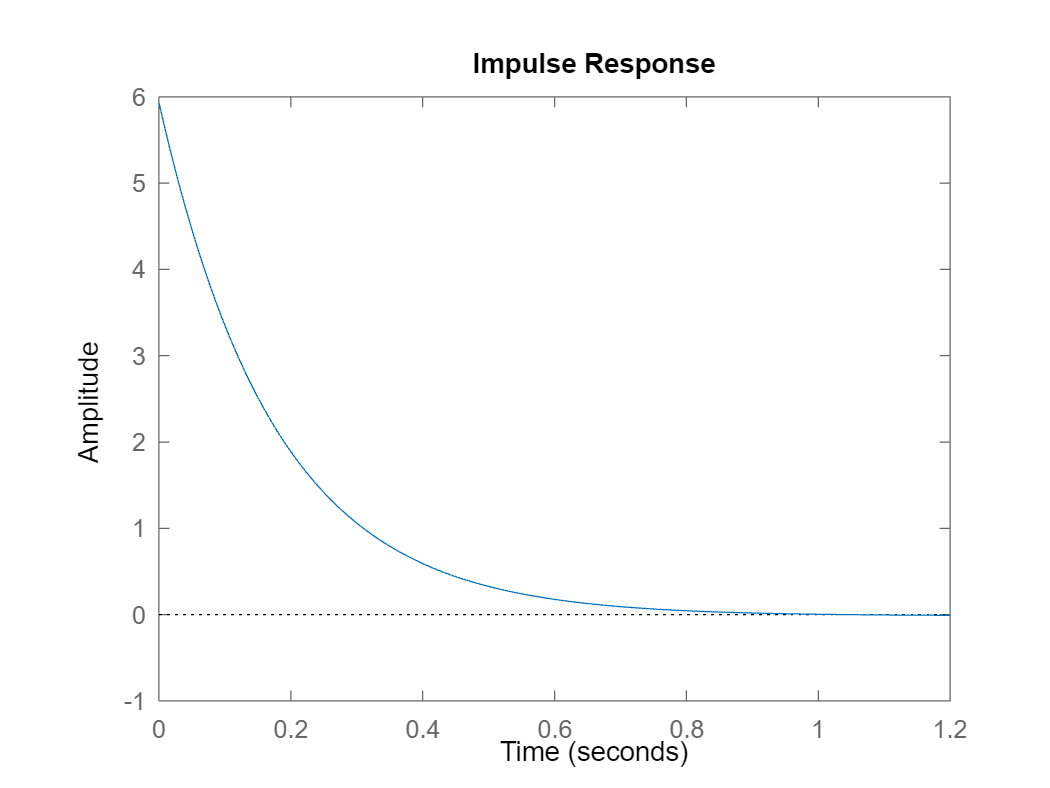

impulse(PID_cl)